# Histogram matching

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

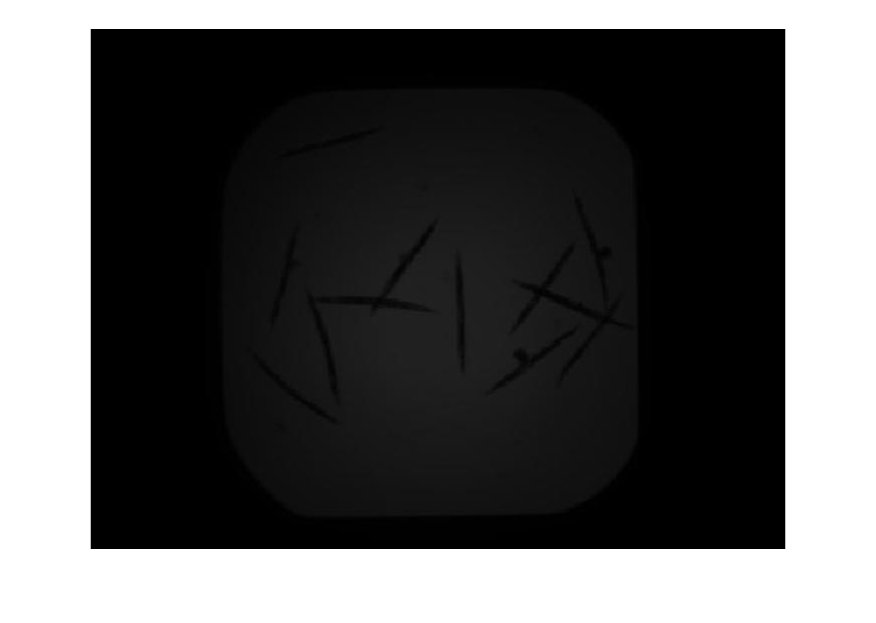

roundworms = imread("./images/worms.jpg");
imshow(roundworms)

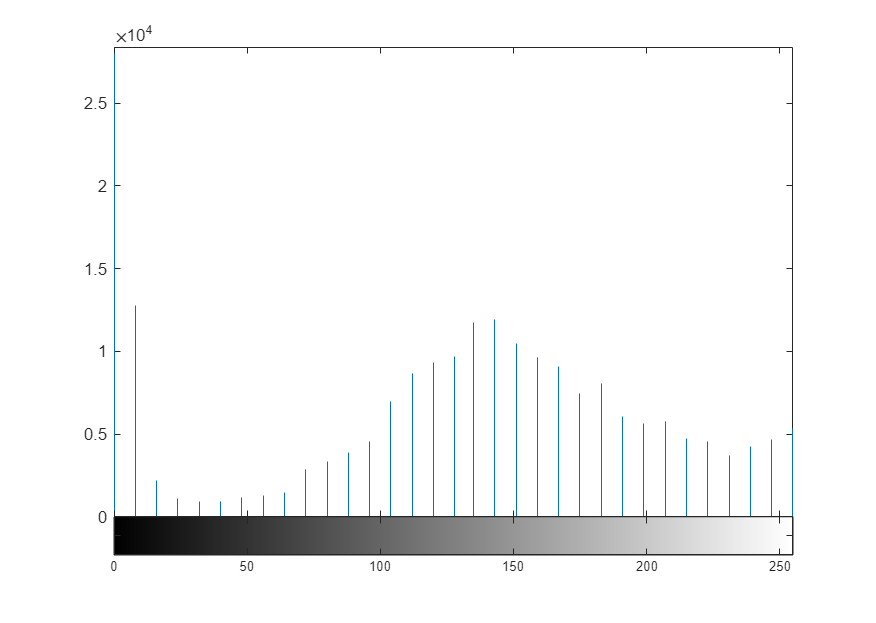

rwAdj = imadjust(roundworms);
imhist(rwAdj)

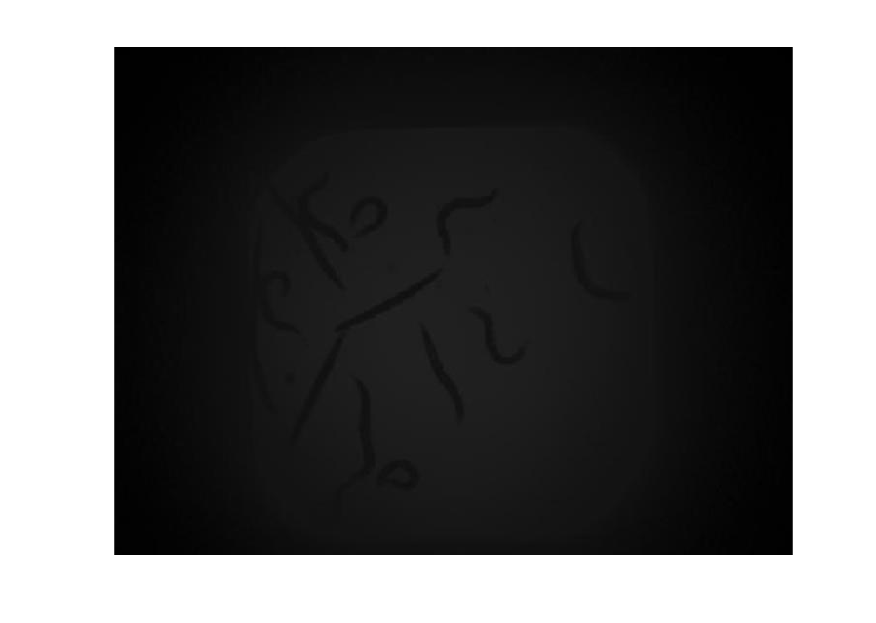


roundworms2 = imread("./images/worms2.jpg");
imshow(roundworms2)

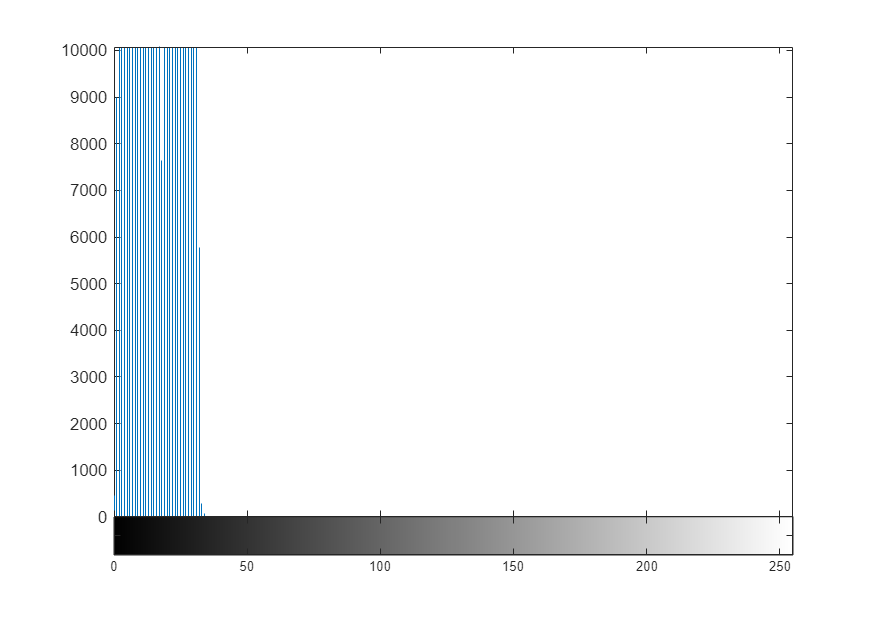

imhist(roundworms2)

## Task 1

Similar to the image `roundworms`, the intensities in `roundworms2` are limited to a small portion of the available range.

rw2Adj = imadjust(roundworms2);

## Task 2

The histograms for `rwAdj` and `rw2Adj` have very different profiles, and the two adjusted images show different levels of contrast. Ideally, the two adjusted histograms would have similar intensity profiles.

To adjust an image `I` to match the intensity profile of a reference image `Iref`, use the `imhistmatch` function.

`Iadj` `=` `imhistmatch``(``I``,``Iref``)``;`

rw2Adj = imhistmatch(roundworms2, rwAdj);

Display the intensity histogram and adjusted images

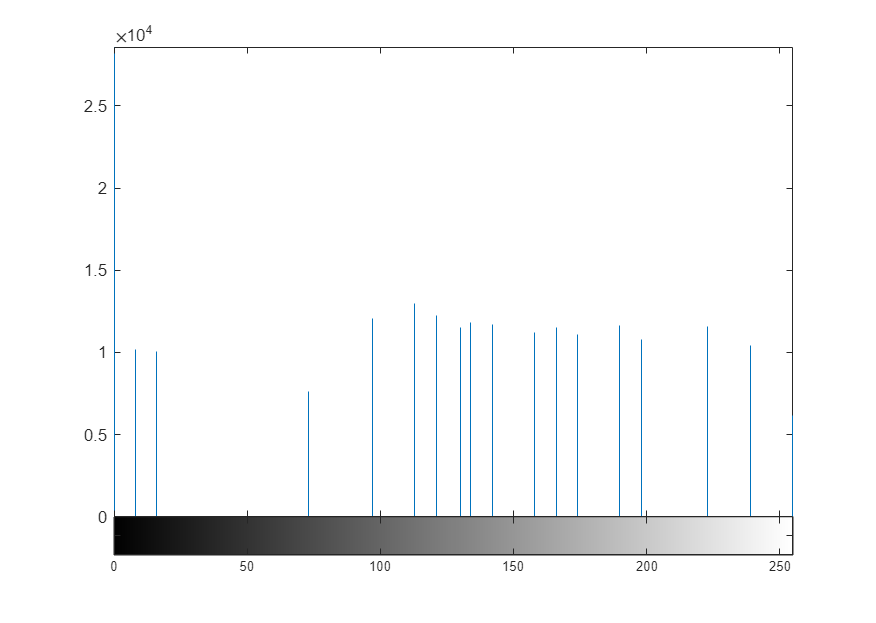

imhist(rw2Adj)

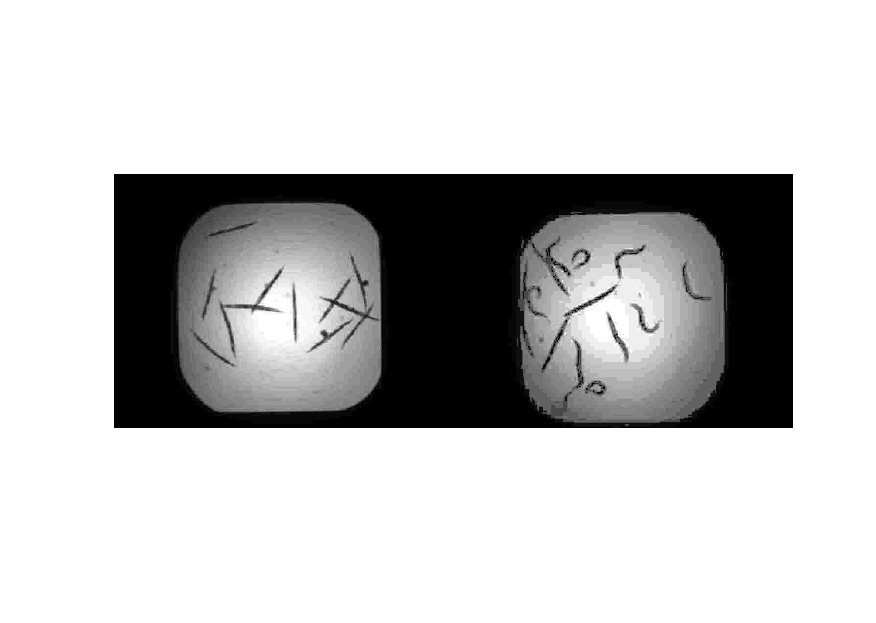

imshowpair(rwAdj, rw2Adj, "montage")